clearvars;
JS = 20;
NN = 15;
phi_perturbations = linspace(0.01,20,NN)*pi/20;

k = -1*ones(NN,JS);
for j = 1:JS
    for n = 1:NN
        %U0 = rand(16,1);
        a = ones(8,1);
        phis = zeros(8,1);
        phis(1) = rand();
        for i = 2:8
            phis(i) = phis(i-1) + rand()*phi_perturbations(n) - phi_perturbations(n)/2;
        end
        U0 =[a;phis];
        
        
        T = 0.1;
        N = 2^12;
        dT = T/(N-1);
        %rescaling as in paper
        tslow = 4000/(2.2*1e+6); 
        hmean = 2*pi*dT/tslow;
        hmax = hmean ;
        hmin = hmean /1000;
        %-----------------------
        tol = 1e-7;
        
        Uevalution = zeros(16,N);
        Uevalution(:,1) = U0;
        
        U1 = U0;
        time = (0:(N-1))*0;
        
        for i = 2:N
          hopt = OptimalStep(@f,time(i),U1,tol,hmean,hmin,hmax);  
          U1 = RK5(@f,time(i),U1,hopt);
        
          time(i+1) = time(i) + hopt;
          Uevalution(:,i) = U1;
        end
        
        time = time(1:end-1)*tslow/ (2*pi);
        phi = Uevalution(9:end,:);
        AD1 = circshift(eye(8),1,2);
        dj = abs(rem((AD1*phi - phi),2*pi));
        aj = Uevalution(1:8,:);
        dj_true = abs(dj(:,end) - rem(dj(:,end),pi)*2);
        %k(n,j) = sum(dj(:,end))/(2*pi);
        k(n,j) = sum(dj_true(:,end))/(2*pi);
        
    end
    disp(j);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20



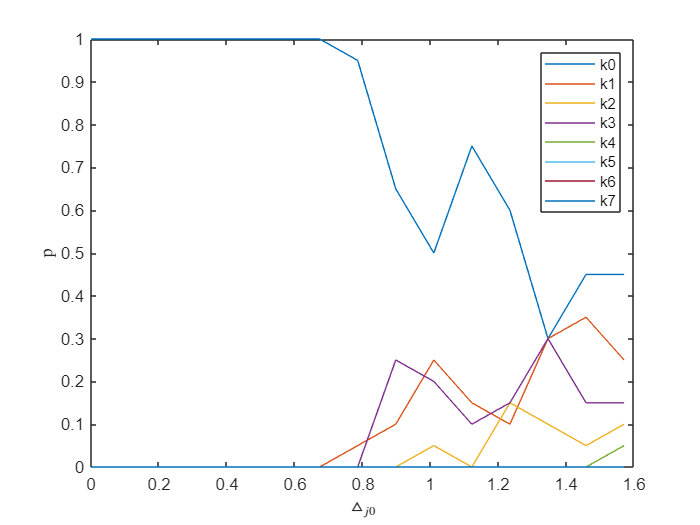

k_approx = round(k);
p = -1*ones(NN,8);
for i = 1:8
    t = (i-1);
    p(:,i) = sum(t*ones(NN,JS) == k_approx,2)/JS;
end

legend("k"+(0:7))
xlabel('$\triangle_{j0}$','Interpreter','latex')
ylabel('p','Interpreter','latex')

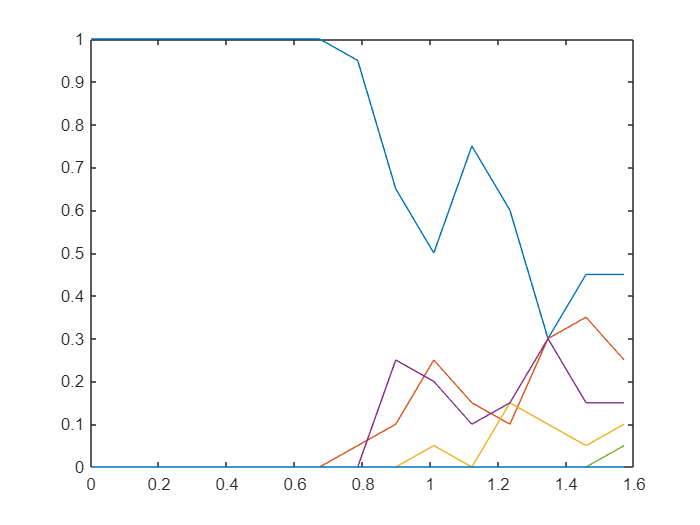

for i =1:8
    plot(phi_perturbations'/2,p(:,i)); hold on
end
hold off

function res = RK5(f,t,u,h) % RK5
    k1 = f(t,u);
    k2 = f(t+1/4*h,u + 1/4*k1*h);
    k3 = f(t+3/8*h,u + 3/32*k1*h + 9/32*k2*h);
    k4 = f(t+12/13*h,u + 1932/2197*k1*h  - 7200/2197*k2*h + 7296/2197*k3*h);
    k5 = f(t+h,u + 439/216*k1*h - 8*k2*h + 3680/513*k3*h - 845/4104*k4*h);
    k6 = f(t+1/2,u - 8/27*k1*h + 2*k2*h - 3544/2565*k3*h + 1859/4104*k4*h - 11/40*k5*h);% need to check t+1/2 ??? mb t+1/2h??
    %u_next = u + h*(25/216*k1 + 1408/2565*k3 + 2197/4104*k4 - 1/5*k5);
    u_next = u + h*(16/135*k1 + 6656/12825*k3 + 28561/56430*k4 - 9/50*k5 + 2/55*k6);

    res = u_next;
end
function res = OptimalStep(f,t,u,tol,h,hmin,hmax)
    k1 = f(t,u);
    k2 = f(t+1/4*h,u + 1/4*k1*h);
    k3 = f(t+3/8*h,u + 3/32*k1*h + 9/32*k2*h);
    k4 = f(t+12/13*h,u + 1932/2197*k1*h  - 7200/2197*k2*h + 7296/2197*k3*h);
    k5 = f(t+h,u + 439/216*k1*h - 8*k2*h + 3680/513*k3*h - 845/4104*k4*h);
    k6 = f(t+1/2,u - 8/27*k1*h + 2*k2*h - 3544/2565*k3*h + 1859/4104*k4*h - 11/40*k5*h);% need to check t+1/2 ??? mb t+1/2h??
    u4_next = u + h*(25/216*k1 + 1408/2565*k3 + 2197/4104*k4 - 1/5*k5);
    u5_next = u + h*(16/135*k1 + 6656/12825*k3 + 28561/56430*k4 - 9/50*k5 + 2/55*k6);
    E = max(u5_next - u4_next);
    hopt = h*(tol/E)^(1/5);
    hopt = min(hmax,hopt);
    %hopt = hnew;
    res = hopt;
end

function res = f(t,U)
    w = [(1:8)*0]';
    Alpha = 0.1;%0.08
    Betta = 0.5; %0.4
    res = fun(U,Alpha,Betta,w);
end

function res = fun(U,alpha,Betta,w)
    a = U(1:8);
    phi = U(9:16);
    AD1 = circshift(eye(8),1,2);
    Re1 = circshift(eye(8),-1,2);
    fa = (1 - a)./2 - Betta/2*(AD1*a.*sin(AD1*phi -phi)+Re1*a.*sin(Re1*phi - phi));
    fphi = w + alpha*a.^2 - Betta + Betta./(2*a).*(AD1*a.*cos(AD1*phi-phi)+Re1*a.*cos(Re1*phi-phi));
    res = [fa;fphi];
end
